clear all;

% Create Mesh
x1      = linspace(0, 2*pi, 50);
x2      = linspace(0, 2*pi, 50);
[xv,yv] = meshgrid(x1,x2);
[F,V]   = mesh2tri(xv,yv,zeros(size(xv)),'x');
s.coord  = V(:,1:2);
s.connec = F;
mesh = Mesh.create(s);


% Create Scalar Domain Function
s.operation = @(xV) xV;
s.mesh      = mesh;
linear = DomainFunction(s);

s.operation = @(xV) xV.^2;
s.mesh      = mesh;
quadratic = DomainFunction(s);

% Scalar Function Times Scalar Function
% Lets consider f(x) = x and g(x) = x^2. We want to compute h(x) = f(x)g(x)

cubic = linear.*quadratic 

cubic =   DomainFunction with properties:

    operation: @(xV)aOp(xV).*bOp(xV)
         mesh: [1×1 SurfaceMesh]
        ndimf: 1


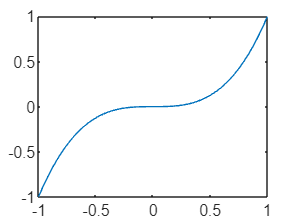

x = linspace(-1,1,50);
plot(x,cubic.evaluate(x))

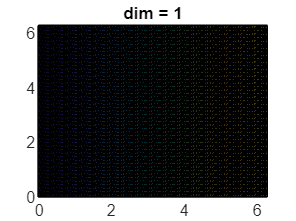


% Create Vector Domain Function
linear = LagrangianFunction.create(mesh,1,'P1');
dofs = linear.getDofCoord;
linear.setFValues(dofs(:,1));
linear.plot();

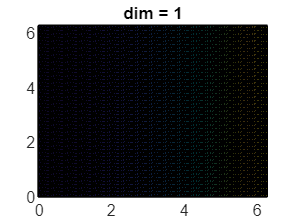


quadratic = LagrangianFunction.create(mesh,1,'P1');
dofs = quadratic.getDofCoord;
quadratic.setFValues(dofs(:,1).^2);
quadratic.plot();


% Scalar times Scalar
cubic = linear.*quadratic

cubic =   DomainFunction with properties:

    operation: @(xV)aOp(xV).*bOp(xV)
         mesh: [1×1 SurfaceMesh]
        ndimf: 1


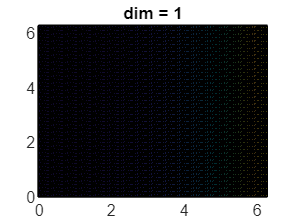

cubic.plot()

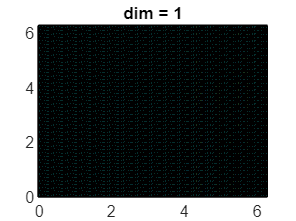


% Scalar Product
dot = DP(Grad(linear), Grad(linear));
dot.plot();

 
% Scalar times Vector
s.operation = @(xV) linear.evaluate(xV)

s = struct with fields:
        coord: [4901×2 double]
       connec: [9604×3 double]
    operation: @(xV)linear.evaluate(xV)
         mesh: [1×1 SurfaceMesh]


s.mesh      = mesh;
linearDF = DomainFunction(s);

product = linearDF.*Grad(linear);
% product.plot();

